# **Questão 2**

**Gabriel Tavares 10773801**

## a) Programa entregue na experiência 5

Aqui está resumido o programa da experiência 5. Usando apenas a parte final dde decodificação e codificação. 

O que acontece nesse script:   

**Codificação** 

- Lemos a imagem da Lenna

- Transformamos a imagem em um único vetor continuo de bits -1 e +1

- Geramos um código **c** 

- Multiplicamos cada bit do vetor pelo código **c** para ter uma mensagem com valores {**-c,+c**}

- Lemos a música

- Dividimos a música em trechos de 512 amostras

- Para cada trecho calculamos a mascara de limiar psicoacústico e fazemos um filtro com essa mascara 

- Em cada trecho filtramos a mensagem pelo filtro da máscara psicoacústica para gerar a marca d'agua

- Por fim somamos a marca d'agua a música

Se tudo correr certo, devemos ter uma música com uma marca d'agua inaudível

**Decodificação**

- Recebemos uma música somada a macar d'agua inaudível

- Dividimos a música em trechos de 512 amostras e em cada trecho calculamos a mascara psicoacústica

- Com essa máscara criamos um filtro inverso bastante próximo do filtro anterior em cada trecho

- Passamos cada trecho da música pelo filtro inverso a fim de extrair a marca d'agua da múscia

- Depois passamos esse sinal filtrado por um filtro Weiner para extrair a mensagem final

- Para extrair a mensagem, aplicamos o produto vetorial entre o trecho de código e o código original e verificamos seu sinal

**Reconstrução**

- Por fim reinterpretamos a mensagem como imagem

- Agrupamos os bits de 8 em 8

- Transformamos os bits em inteiro novamente

- Recriamos a matriz a partir do vetor de mensagens

% LEITURA DA IMAGEM ===============
lenna = imread('lenna64.jpg');

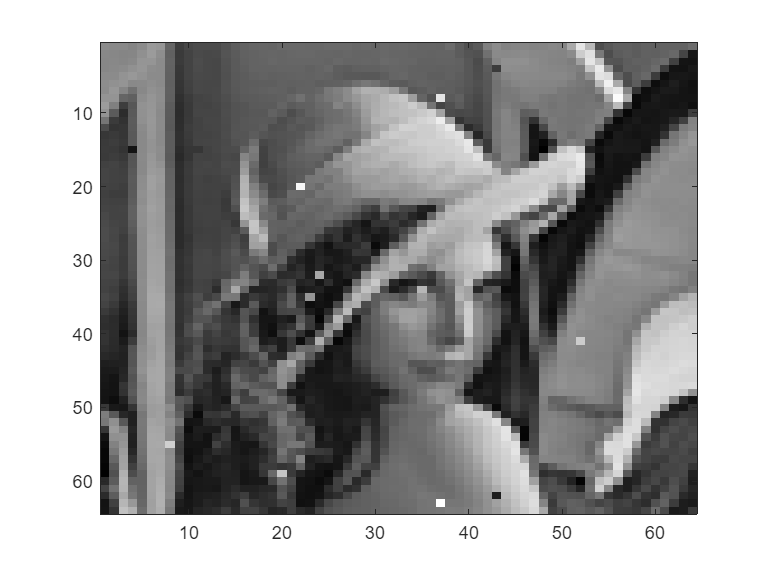

% CRIAÇÃO DA MENSAGEM ===============
M = 64*64*8;

lenna_bin = dec2bin(lenna);
lenna_col = reshape(lenna_bin,2^15,1);
am = 2*str2num(lenna_col) - 1;

fa = 44.1e3;
R = 100;
g = 1;
rand('seed',12345);
Nb = fa / R;

c = 2*round(rand(Nb,1)) - 1; % codigo

v = kron(am,c); % sinal modulado

% LEITURA DA MUSICA ===============
load('fspecial_matriz.mat')
[musica, fs] = audioread('BeethovenExp5.wav');
x = musica;

% CRIAÇÃO DA MARCA DAGUA ===================
w = zeros(length(musica),1);
z = zeros(length(musica),1);
y = zeros(length(musica),1);

zs = zeros(50,1);
Nblocos = floor(length(musica)/512);

for i = (0:Nblocos-1)
    mascara = psychoacoustical_model( musica(i*512+1 : (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [w(i*512+1: (i+1)*512), zs] = filter(b0, ai ,v(i*512+1: (i+1)*512), zs);

    y(i*512+1: (i+1)*512) = w(i*512+1: (i+1)*512) + x(i*512+1: (i+1)*512);
end


% DECODIFICAÇÃO DA MARCA DAGUA =====================

% filtro psicoacustico
zs = zeros(50,1);
for i = (0: floor(length(musica)/512 - 1))
    mascara = psychoacoustical_model( y(i*512+1: (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [z(i*512+1: (i+1)*512), zs]= filter(ai, b0 ,y(i*512+1: (i+1)*512), zs);
end

% filtro de wiener
Nfiltro = 50;
correlacao_v= xcorr(v,Nfiltro,'biased');
zs = zeros(2*Nfiltro,1);
pre_dem = zeros(length(musica),1);
saidaWiener = zeros(length(musica),1);

Nblocos = floor(length(musica)/512);

for i = (0: Nblocos-1)
    correlacao_z = xcorr(z(i*512+1: (i+1)*512), 2*Nfiltro, 'biased');
    
    autocorr_z = toeplitz(correlacao_z(2*Nfiltro+1:end));
    
    h = autocorr_z\correlacao_v;
    
    [saidaWiener(i*512+1: (i+1)*512), zs] = filter(h,1,z(i*512+1: (i+1)*512), zs);
    pot_Wiener = sum(saidaWiener(i*512+1: (i+1)*512).*saidaWiener(i*512+1: (i+1)*512))/512;
    
    if pot_Wiener > 0
        saidaWiener(i*512+1: (i+1)*512) = saidaWiener(i*512+1: (i+1)*512)/sqrt(pot_Wiener);
    end
    
end

pre_dem(1:end-Nfiltro) = saidaWiener(Nfiltro+1:end);

% RECONSTRUÇÃO DA IMAGEM ===================
ym = reshape(pre_dem,Nb,32768);

alfam = transpose(ym)*c/Nb;
BER = 10*log10(sum(abs(sign(alfam) - am)/2)/length(am));
b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2,"%1.0f");
lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

mmsim = ssim_index(lenna, nova_lenna, [0.01 0.03], matriz, 255);

figure()
colormap(gray)
imagesc(nova_lenna)

Dessa forma, tivemos os seguintes resultados

- **BER** : -29.7138 em escala logaritima

- **MMSIM**: 0.9778

## b) Codificação da música com mp3

y_mp3 = mp3_codec(y, fs);

Analyzing frame   100 / 451569
Analyzing frame   200 / 451569
Analyzing frame   300 / 451569
Analyzing frame   400 / 451569
Analyzing frame   500 / 451569
Analyzing frame   600 / 451569
Analyzing frame   700 / 451569
Analyzing frame   800 / 451569
Analyzing frame   900 / 451569
Analyzing frame  1000 / 451569
Analyzing frame  1100 / 451569
Analyzing frame  1200 / 451569
Analyzing frame  1300 / 451569
Analyzing frame  1400 / 451569
Analyzing frame  1500 / 451569
Analyzing frame  1600 / 451569
Analyzing frame  1700 / 451569
Analyzing frame  1800 / 451569
Analyzing frame  1900 / 451569
Analyzing frame  2000 / 451569
Analyzing frame  2100 / 451569
Analyzing frame  2200 / 451569
Analyzing frame  2300 / 451569
Analyzing frame  2400 / 451569
Analyzing frame  2500 / 451569
Analyzing frame  2600 / 451569
Analyzing frame  2700 / 451569
Analyzing frame  2800 / 451569
Analyzing frame  2900 / 451569
Analyzing frame  3000 / 451569
Analyzing frame  3100 / 451569
Analyzing frame  3200 / 451569
Analyzin

sound(y_mp3(20*fs:25*fs), fs);

O sinal que passou pelo codec_mp3 continua com uma marca d'água imperceptível

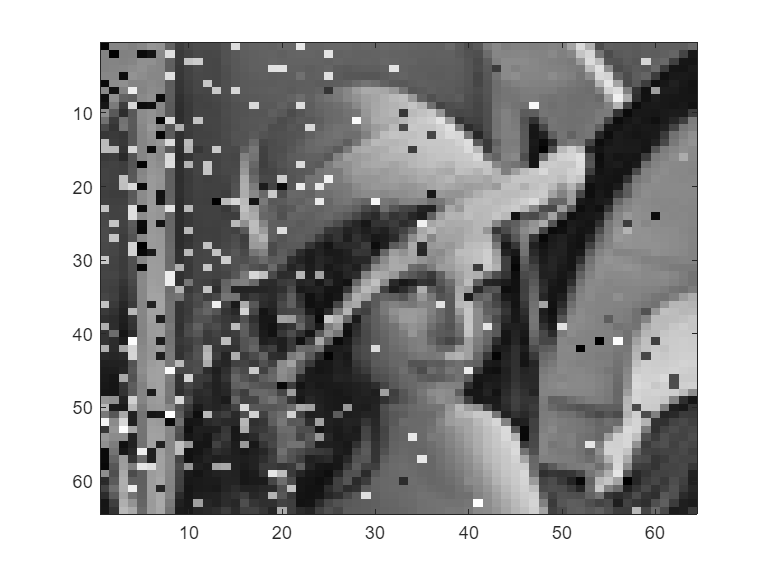

% DECODIFICAÇÃO DA MARCA DAGUA =====================

y = y_mp3;

% filtro psicoacustico
zs = zeros(50,1);
for i = (0: floor(length(musica)/512 - 1))
    mascara = psychoacoustical_model( y(i*512+1: (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [z(i*512+1: (i+1)*512), zs]= filter(ai, b0 ,y(i*512+1: (i+1)*512), zs);
end

% filtro de wiener
Nfiltro = 50;
correlacao_v= xcorr(v,Nfiltro,'biased');
zs = zeros(2*Nfiltro,1);
pre_dem = zeros(length(musica),1);
saidaWiener = zeros(length(musica),1);

Nblocos = floor(length(musica)/512);

for i = (0: Nblocos-1)
    correlacao_z = xcorr(z(i*512+1: (i+1)*512), 2*Nfiltro, 'biased');
    
    autocorr_z = toeplitz(correlacao_z(2*Nfiltro+1:end));
    
    h = autocorr_z\correlacao_v;
    
    [saidaWiener(i*512+1: (i+1)*512), zs] = filter(h,1,z(i*512+1: (i+1)*512), zs);
    pot_Wiener = sum(saidaWiener(i*512+1: (i+1)*512).*saidaWiener(i*512+1: (i+1)*512))/512;
    
    if pot_Wiener > 0
        saidaWiener(i*512+1: (i+1)*512) = saidaWiener(i*512+1: (i+1)*512)/sqrt(pot_Wiener);
    end
    
end

pre_dem(1:end-Nfiltro) = saidaWiener(Nfiltro+1:end);

% RECONSTRUÇÃO DA IMAGEM ===================
ym = reshape(pre_dem,Nb,32768);

alfam = transpose(ym)*c/Nb;
BER = 10*log10(sum(abs(sign(alfam) - am)/2)/length(am));
b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2,"%1.0f");
lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

mmsim = ssim_index(lenna, nova_lenna, [0.01 0.03], matriz, 255);

figure()
colormap(gray)
imagesc(nova_lenna)

**Análise**

Passando o sinal de música com marca d'água pelo code mp3 notamos que o sinal de marca d'água continua inaudível, porém há uma perda na recepção da mensagem. 

Dessa forma temos:

- **BER: **-18.72 em escala logarítima

- **MSSIM: **0.6795